# WorkSheet 11

Problem 2

% Part 1
g = @(x) x +1;
g_prime = @(x) 1;
tol = 10^-5;
x0 = -10;
x = newtons_method (g,g_prime, x0, tol);
root = x(end)

root = -1

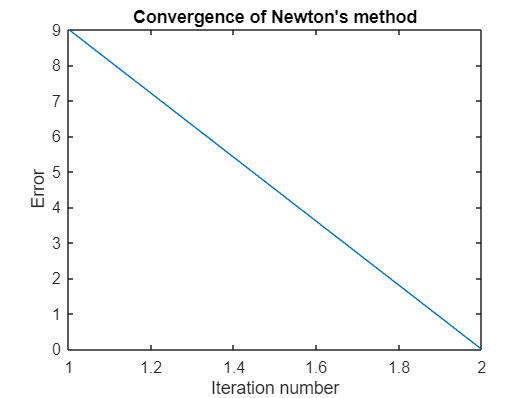

iterations = 1:length(x);
error = abs(g(x));
figure
plot(iterations, error)
xlabel('Iteration number')
ylabel('Error')
title('Convergence of Newton''s method')


% Part 2
g = @(x) x + sin(x);
g_prime = @(x) 1 + cos(x);
tol = 10^-5;
x0 = pi/4;
x = newtons_method (g, g_prime, x0, tol);
root = x(end)

root = -2.6832e-13

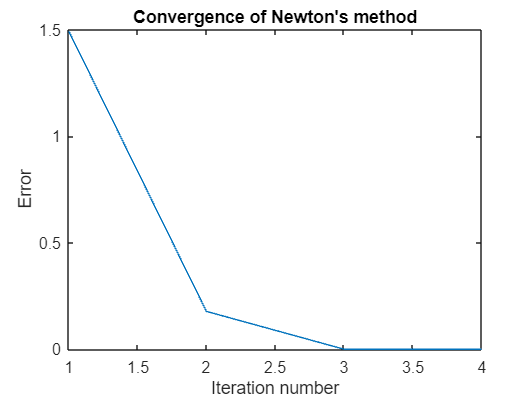

iterations = 1:length(x);
error = abs(g(x));
figure
plot(iterations, error)
xlabel('Iteration number')
ylabel('Error')
title('Convergence of Newton''s method')



% Part 3
g = @(x) x.^2 -7*(x)+ 12;
g_prime = @(x) 2*x - 7;
tol = 10^-5;
x0 = 5;
x = newtons_method (g, g_prime, x0, tol);
root_1= x(end)

root_1 = 4.0000


figure
% Initial guess x0 = 5
iterations = 1:length(x);
error = abs(g(x));
hold on
plot(iterations, error)
% Initial guess x0 = 0
x0 = 0;
x = newtons_method (g, g_prime, x0, tol);
root_2 = x(end)

root_2 = 3.0000

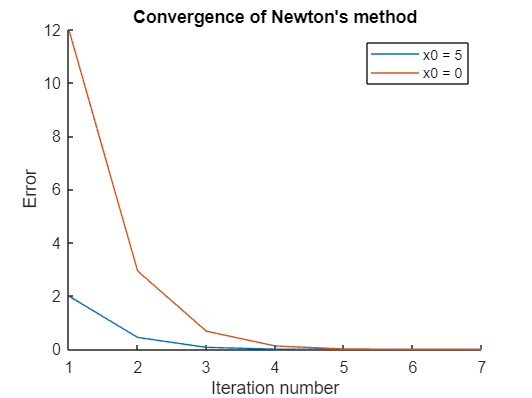

iterations = 1:length(x);
error = abs(g(x));
plot(iterations, error)
hold off
xlabel('Iteration number')
ylabel('Error')
title('Convergence of Newton''s method')
legend('x0 = 5','x0 = 0')

Problem 3

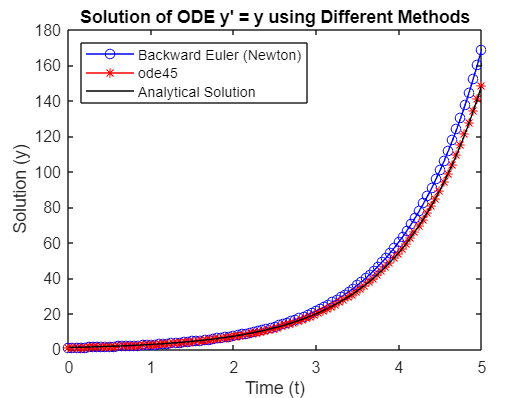

% Part A
f = @(t,y) y;
df = @(t,y) 1;
tspan = linspace(0,5);  
tol = 10^-5;
ic = 1;
nsteps = 100;
[t_be, y_be] = backward_euler_newton(f,df,tspan,ic, nsteps,tol);

[t_ode45, y_ode45] = ode45(f, tspan, ic);

t_analytical = linspace(0,5,1000);
y_analytical = exp(t_analytical);

figure;
plot(t_be,y_be, 'b-o', t_ode45, y_ode45, 'r-*', t_analytical, y_analytical, 'k')
legend('Backward Euler (Newton)', 'ode45', 'Analytical Solution', 'Location', 'NorthWest');
title('Solution of ODE y'' = y using Different Methods');
xlabel('Time (t)');
ylabel('Solution (y)');

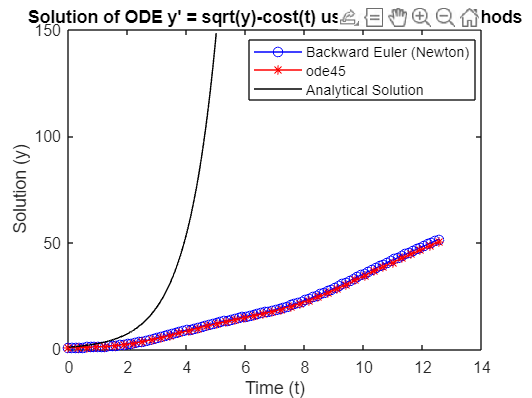

% The models are pretty accurate with a small amount of tol and a smaller
% amount of nsteps showing that less computational cost is wasted on this
% graph.

% Part B
f_2 = @(t,y) sqrt(y)-cos(t);
df_2 = @(t, y) 1 / (2 * sqrt(y));
tspan = [0 4*pi];
ic = 1;
tol = 10^-3;
nsteps = 100;
[t_1b, y_1b] = backward_euler_newton(f_2,df_2,tspan,ic, nsteps,tol);
[t_2, y_2] = ode45(f_2, tspan, ic);

t_analytical_B = linspace(0,5,1000);
y_analytical_B = exp(t_analytical);

figure;
plot(t_1b,y_1b, 'b-o', t_2, y_2, 'r-*', t_analytical_B, y_analytical_B, 'k')
legend('Backward Euler (Newton)', 'ode45', 'Analytical Solution', 'Location', 'Best');
title('Solution of ODE y'' = sqrt(y)-cost(t) using Different Methods');
xlabel('Time (t)');
ylabel('Solution (y)');

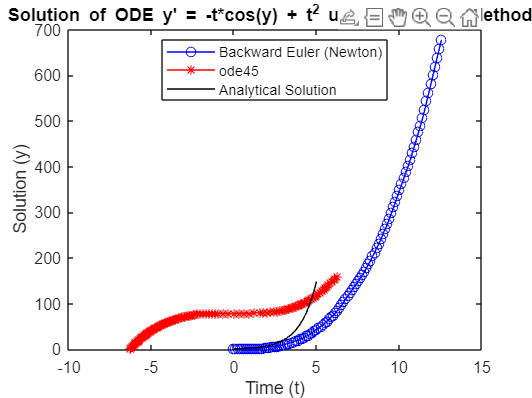

% The models are pretty accurate with ode45 and backward_euler_newton being almost the same trajectory, also with a small amount of tol and a smaller
% amount of nsteps showing that less computational cost is wasted on this
% graph.

% Part C
f_3 = @(t, y) -t*cos(y) + t^2;
df_3 = @(t, y) t*sin(y);
tspan = [-2*pi 2*pi];
ic = 1;
tol = 10^-1;
nsteps = 100;
[t_1c, y_1c] = backward_euler_newton(f_3,df_3,tspan,ic, nsteps,tol);
[t_3, y_3] = ode45(f_3, tspan, ic);

t_analytical_C = linspace(0,5,1000);
y_analytical_C = exp(t_analytical);

figure;
plot(t_1c,y_1c, 'b-o', t_3, y_3, 'r-*', t_analytical_C, y_analytical_C, 'k')
legend('Backward Euler (Newton)', 'ode45', 'Analytical Solution', 'Location', 'Best');
title('Solution of ODE y'' = -t*cos(y) + t^2 using Different Methods');
xlabel('Time (t)');
ylabel('Solution (y)');

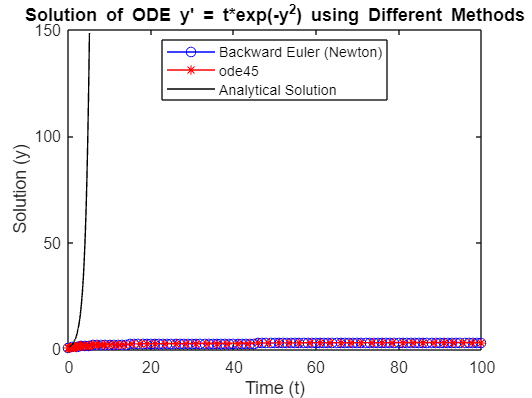

% The backward euler newton and the ode45 are very far from each other with
% analytical solution being closer to the backward euler newton in their
% bases. This showcase how an smaller tol could make the
% backward_euler_newton function more accurate and a larger nsteps Increases the overall accuracy of the Backward Euler method by reducing the size of each time step, at the cost of more total iterations (and thus, potentially, a higher computational cost).

% Part D
f_4 = @(t,y) t*exp(-y^2);
df_4 = @(t, y) -2*t*y*exp(-y^2);
ic = 1;
tol = 10^-4;
tspan = [0 100];
nsteps = 100;
[t_1d, y_1d] = backward_euler_newton(f_4,df_4,tspan,ic, nsteps,tol);
[t_4, y_4] = ode45(f_4, tspan, ic);

t_analytical_D = linspace(0,5,1000);
y_analytical_D = exp(t_analytical);

figure;
plot(t_1d,y_1d, 'b-o', t_4, y_4, 'r-*', t_analytical_D, y_analytical_D, 'k')
legend('Backward Euler (Newton)', 'ode45', 'Analytical Solution', 'Location', 'Best');
title('Solution of ODE y'' = t*exp(-y^2) using Different Methods');
xlabel('Time (t)');
ylabel('Solution (y)');

% The backward_Euler_newton and the ode45 are closely tied together meaning
% that the tol and nsteps may be too big (for tol) and too small (for
% nsteps) causing it to be inaccurate form the anaytical solutions of the
% problem. However, if looking just at the backward_euler_newton and ode45
% we have created the best fit for the both since they follow the exact
% same path.